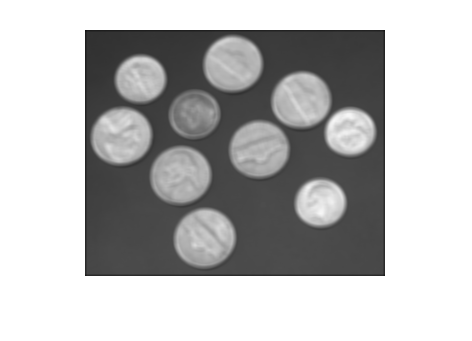

img = imread('text.png');
%L = bwlabel(img, conn) %conn means connectivity, which is either 4 or 8
cc = bwconncomp(img);

%cellfun() applies a certain function to each array cell

pixels = cellfun(@numel, cc.PixelIdxList);
[biggest, index] = max(pixels);
im(cc.PixelIdxList{index}) = 0;

% img2 = imfilter(img, kernel);
img = imread('coins.png');
boxfilter = ones(5,5)/25; % or (3,3)/9
img2 = imfilter(img, boxfilter);
%imshow(img2)

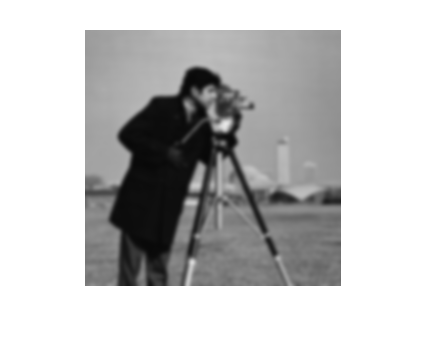

%B = padarray(A, padsize);
%B = padarray(A, padsize, padval)
img3 = imread('cameraman.tif');
img4 = padarray(img3, 3);
%imshow(img4)
img5 = imfilter(img3, boxfilter, 'replicate');
%imshow(img5)

img6 = imgaussfilt(img3, 2);
imshow(img6)

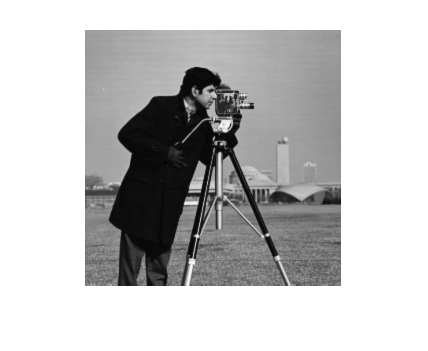

img7 = imgaussfilt(img3);
imshow(img7)

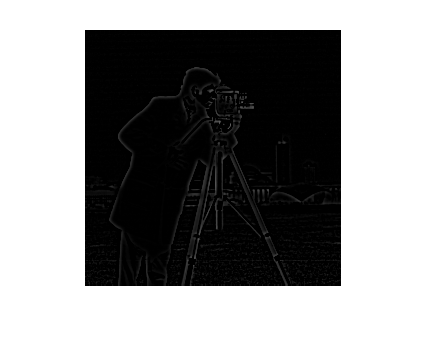

imshow(img6-img7)